clc;
clear;

%VÁLVULA
num = 1;
den = [1 0];
val = tf(num, den)

val =
 
  1
  -
  s
 
Continuous-time transfer function.
Model Properties



%TANQUE
num = 1;
den = [1 2];
tanqu = tf(num, den)

tanqu =
 
    1
  -----
  s + 2
 
Continuous-time transfer function.
Model Properties



%REDUÇÃO DE BLOCOS
G1 = series(val, tanqu);
G = feedback(G1, 1)

G =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


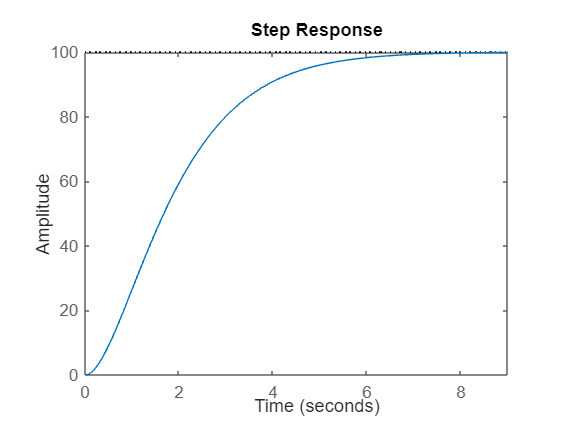


%RESPOSTA DO SISTEMA
    %R = 100
step(G*100)

stepinfo(G*100)

ans = struct with fields:
         RiseTime: 3.3579
    TransientTime: 5.8339
     SettlingTime: 5.8339
      SettlingMin: 90.0022
      SettlingMax: 99.9396
        Overshoot: 0
       Undershoot: 0
             Peak: 99.9396
         PeakTime: 9.7900


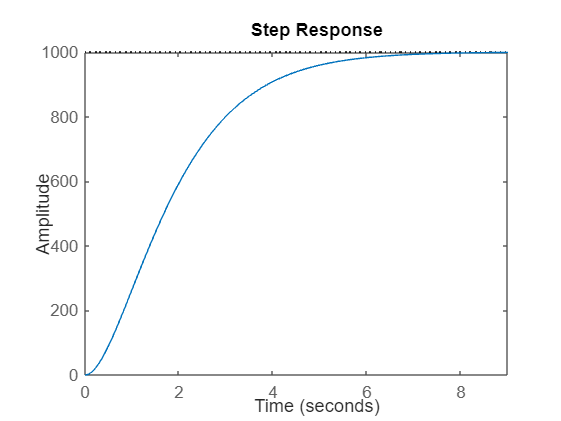

    %R = 100
step(G*1000)

stepinfo(G*1000)

ans = struct with fields:
         RiseTime: 3.3579
    TransientTime: 5.8339
     SettlingTime: 5.8339
      SettlingMin: 900.0223
      SettlingMax: 999.3957
        Overshoot: 0
       Undershoot: 0
             Peak: 999.3957
         PeakTime: 9.7900
